# Cake eating problem

problem: 

        
$$\[
\max_{u_0,\dots,u_{N-1}} \left[ \alpha^N g_N(x_N) + \sum_{k=0}^{N-1} \alpha^k g_k(x_k, u_k, w_k) \right]
\]$$


variables:

        
$$x_0: Initial\ cake\ size
$$


        
$$N: Number\ of\ time\ steps\ (\ portions\ / \ days\ )
$$


        
$$x_k: Cake\ size\ at\ time\ k = 1, . . . , N
$$


        
$$u_k: Amount\ of\ eaten\ cake\ at\ time\ k = 0, . . . , N - 1
$$


        
$$\alpha  : Discount\ factor\ –\ cake\ getting\ stale$$
   

system model:

        
$$x_{k+1} = x_k - u_k
$$


        
$$g(x_k, u_k, w_k) = 2\sqrt{u_k}
$$


        
$$
g_N(x_N) = 0$$


## Dynamic programming

dp algorithm: 

        
$$\[
J_N(x_N) = g_N(x_N) = 0
\]
\[
J_k(x_k) = \min_{u_k \in U_k(x_k)} \, E \left\{ g_k(x_k, u_k, w_k) + \alpha J_{k+1}(f_k(x_k, u_k, w_k)) \right\} = \min_{u_k \in U_k(x_k)} \left\{ g_k(x_k, u_k) + \alpha J_{k+1}(x_k - u_k) \right\} 
\]$$


variables:

        
$$x_0: Initial\ cake\ size
$$


        
$$N: Number\ of\ time\ steps\ (\ portions\ / \ days\ )
$$


        
$$x_k: Cake\ size\ at\ time\ k = 1, . . . , N
$$


        
$$u_k: Amount\ of\ eaten\ cake\ at\ time\ k = 0, . . . , N - 1
$$


        
$$\alpha  : Discount\ factor\ –\ cake\ getting\ stale$$


system model:

        
$$x_{k+1} = x_k - u_k
$$


        
$${g(x_k, u_k, w_k) = -2\sqrt{u_k}
$$


        
$$
g_N(x_N) = 0$$


### Analytic solution:


$$Time\ k = N:$$


        
$$\[
J_N(x_N) = g_N(x_N) = 0
\]$$



$$Time\ k = N-1:$$


        
$$\[
J_{N-1}(x_{N-1}) = \min_{0\leq u_{N-1} \leq x_{N-1}} \left\{ -2\sqrt{u_{N-1}} + \alpha\cdot 0 \right\} 
\]
\[
 u_{N-1} = x_{N-1}\ \ J_{N-1} = -2\sqrt{x_{N-1}}+\alpha\cdot0\ \ (\rightarrow x_N = 0)
\]$$



$$Time\ k = N-2:$$


        
$$\[
J_{N-2}(x_{N-2}) = \min_{0\leq u_{N-2} \leq x_{N-2}} \left\{ -2\sqrt{u_{N-2}} + \alpha(x_{N-1})) \right\} = \min_{0\leq u_{N-2} \leq x_{N-2}} \left\{ -2\sqrt{u_{N-2}} + \alpha(-2\sqrt{x_{N-2}-u_{N-2}}) \right\} 
\]
$$



$$\text{Differentation:}$$


        
$$\[
0 = -\frac{1}{\sqrt{u_{N-2}}} + \alpha \frac{1}{\sqrt{x_{N-2} - u_{N-2}}}
\]
$$


        
$$
\[
\frac{1}{u_{N-2}} = \alpha^2 \frac{1}{x_{N-2} - u_{N-2}}
\]
$$


        
$$
\[
u_{N-2} = \frac{x_{N-2} - u_{N-2}}{\alpha^2} \quad \rightarrow \quad u_{N-2} = \frac{x_{N-2}}{\alpha^2 + 1}
\]

$$


        
$$
\[
V_{N-2}(x_{N-2}) = -2\sqrt{\frac{x_{N-2}}{\alpha^2+1}} - 2\alpha \sqrt{x_{N-2}(1-\frac{1}{\alpha^2+1})}
= -2\sqrt{\frac{x_{N-2}}{\alpha^2+1}} - 2\alpha \sqrt{\frac{x_{N-2}\alpha^2}{\alpha^2+1}}
\]

$$


        
$$\[
V_{N-2}(x_{N-2}) = -2\sqrt{\alpha^2+1}\sqrt{x_{N-2}}
\]
$$


        
$$
\[
V_{N-3}(x_{N-3}) = \min_{0 \leq u_{N-3} \leq x_{N-3}}
\left[ -2\sqrt{u_{N-3}} + \alpha (-2\sqrt{\alpha^2+1}\sqrt{x_{N-3}-u_{N-3}}) \right]
\]
$$


        
$$
\[
V_{N-3}(x_{N-3}) = \min_{0 \leq u_{N-3} \leq x_{N-3}}
\left[-2\sqrt{u_{N-3}} + \beta(-2\sqrt{x_{N-3} - u_{N-3}})\right], \text{where}\ \beta = \alpha \sqrt{\alpha^2+1}
\]

$$


        
$$
\[
u_{N-3} = \frac{x_{N-3}}{\beta^2 + 1}, \qquad V_{N-3}(x_{N-3}) = -2\sqrt{\beta^2+1}\sqrt{x_{N-3}}
\]$$



$$\text{From this, we can get the optimal policies and costs in the following way:}$$


        
$$\[
\gamma_0 = --,\qquad u_N = --,\qquad V_N = 0,\\

\gamma_1 = 0,\qquad u_{N-1} = \frac{x_{N-1}}{\gamma_1^2+1},\qquad V_{N-1} = -2\sqrt{\gamma_1^2+1}\sqrt{x_{N-1}},\\
\\
\gamma_2 = \alpha,\qquad u_{N-2} = \frac{x_{N-2}}{\gamma_2^2+1},\qquad V_{N-2} = -2\sqrt{\gamma_2^2+1}\sqrt{x_{N-2}},\\
\\
\gamma_3 = \alpha \sqrt{\gamma_2^2+1},\qquad u_{N-3} = \frac{x_{N-3}}{\gamma_3^2+1},\qquad V_{N-3} = -2\sqrt{\gamma_3^2+1}\sqrt{x_{N-3}},\\
\\
\vdots\\
\\
\gamma_k = \alpha \sqrt{\gamma_{k-1}^2+1},\qquad u_{N-k} = \frac{x_{N-k}}{\gamma_k^2+1},\qquad V_{N-k} = -2\sqrt{\gamma_k^2+1}\sqrt{x_{N-k}},\\
\\
\vdots\\
\\
\gamma_N = \alpha \sqrt{\gamma_{N-1}^2+1},\qquad u_0 = \frac{x_0}{\gamma_N^2+1},\qquad V_0 = -2\sqrt{\gamma_N^2+1}\sqrt{x_0}.
\]
$$


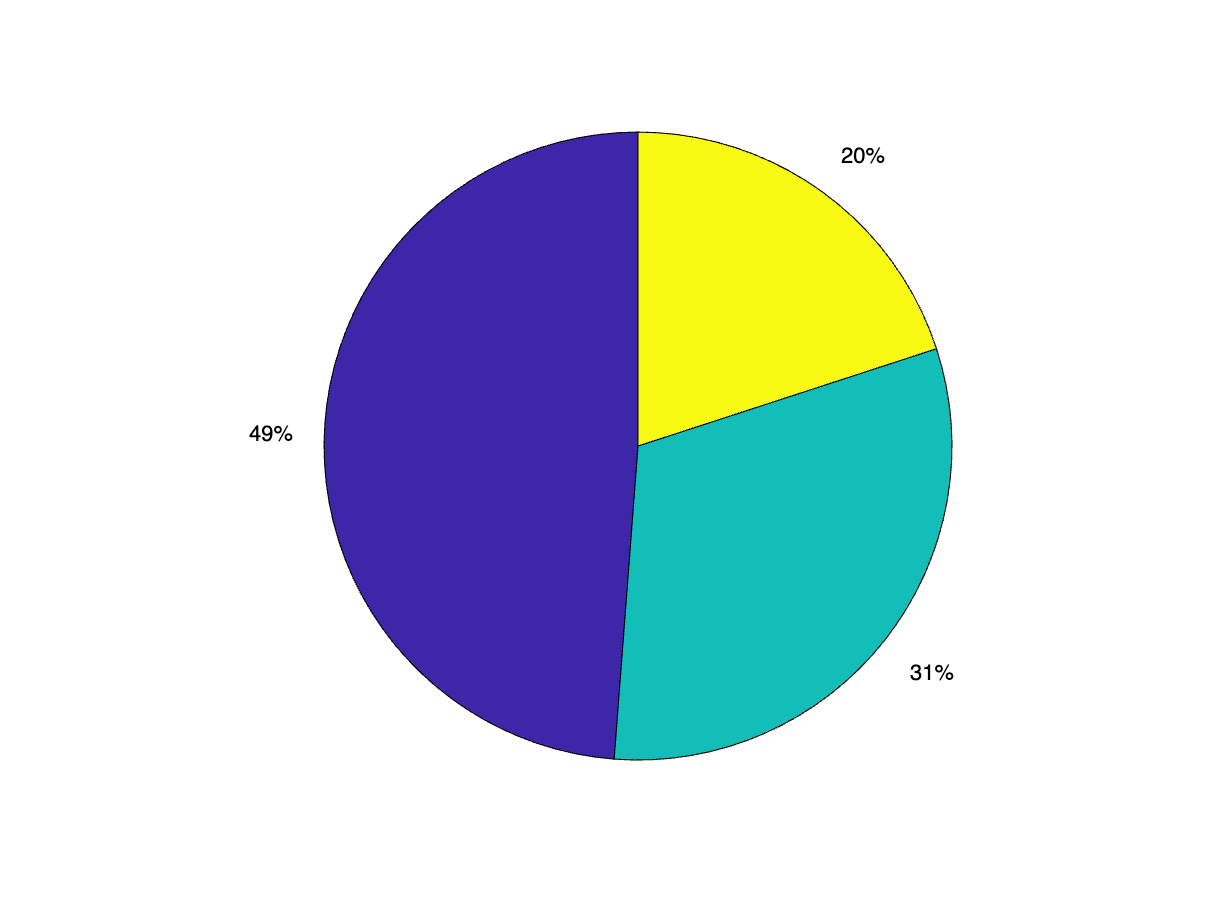

clear; clc; 
N =3;
reduction =20;

alpha = (100 - 20)/100;

x0 = 1;
gamma = zeros(N,1);

for i=2:N
    gamma(i) = alpha*sqrt(gamma(i-1)^2 + 1);
end

u = zeros(N,1);
J = zeros(N+1,1);
xs = zeros(N+1,1);
xs(1)=x0;

for i = 1:N 
    u(i)= xs(i)/(gamma(N-i+1)^2 + 1);
    J(i) = -2*sqrt(gamma(N-i+1)^2 +1)*sqrt(xs(i));
    xs(i+1) = xs(i) - u(i) ;
end

pie(u)

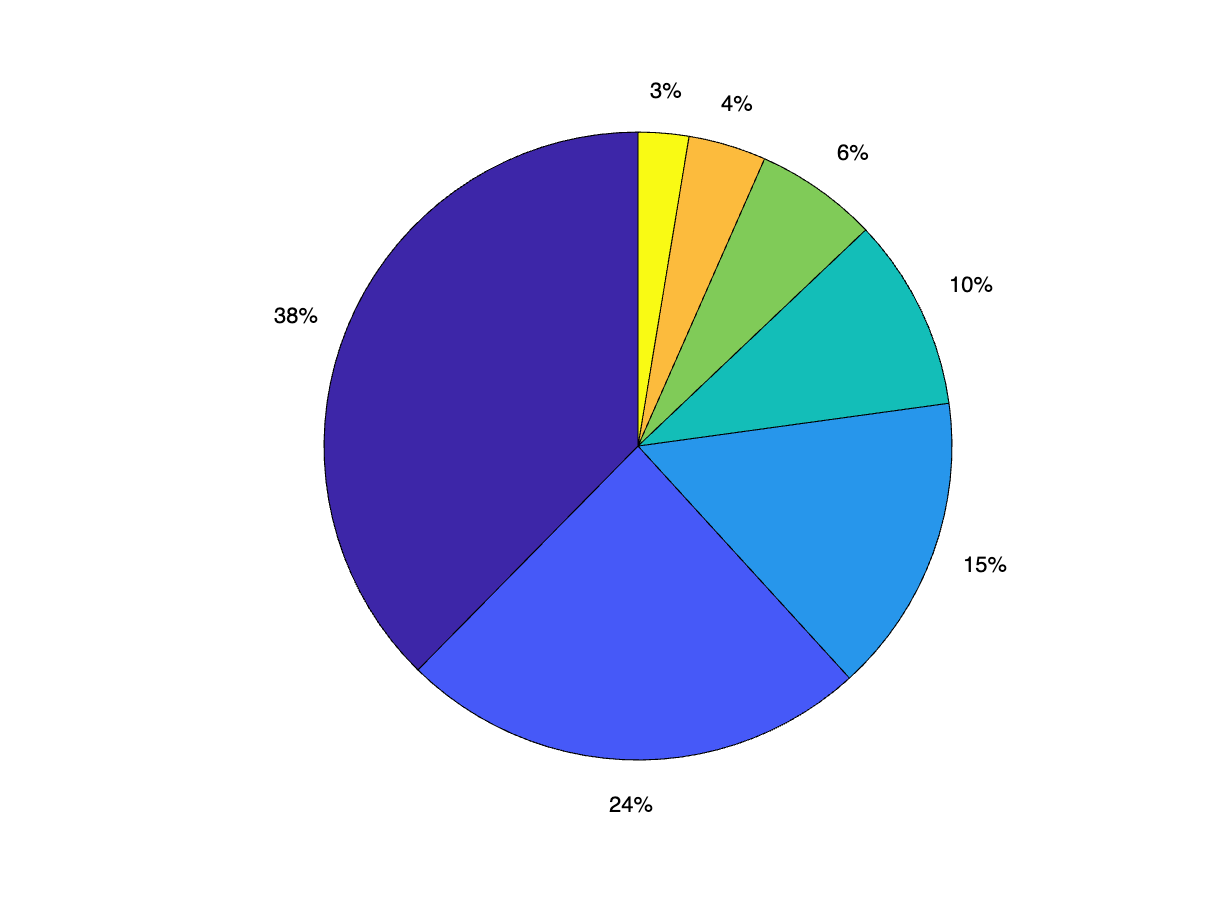

clear; clc; 
N =7;
reduction =20;

alpha = (100 - 20)/100;

%DISCRETIZATION

nb_poits = 1000;
xs = linspace(0,1,nb_poits);

g_k =  @(u_k) -2*sqrt(u_k);
g_N = @(x_k) 0;

mu = NaN*zeros(nb_poits, N);
J = NaN*zeros(nb_poits, N+1);

for i = 1:nb_poits
    J(i,N+1) = g_N(xs(i));
end

for i = N:-1:1
    for ii = 1:nb_poits
        x_curret = xs(ii);
        us = xs(1:ii);
        nb_pos = length(us);
        J_temp = NaN*zeros(nb_pos,1);

        for iii=1:nb_pos
            x_next = xs(ii-iii+1);
            row = ii - iii +1 ;
            J_temp(iii) = g_k(us(iii)) + alpha*J(row, i+1);
        end

        [minval,minpos] = min(J_temp);
        J(ii,i) = minval; mu(ii,i) = us(minpos);

    end 
end 


%%% SOLUTION EXTRACTION %%%
x = 1; %starting size
u_opt = zeros(N,1); %optimal choice arr

for i=1:N
   
    [~, idx] = min(abs(xs - x)); %closest value to current x
    u_opt(i) = mu(idx,i); %choosing correct control
    x = x - u_opt(i); %computing new x 
end
pie(u_opt)

# Cake eating problem - random element

problem: 

        
$$\[
\max_{u_0,\dots,u_{N-1}} \left[ \alpha^N g_N(x_N) + \sum_{k=0}^{N-1} \alpha^k g_k(x_k, u_k, w_k) \right]
\]$$


variables:

        
$$x_0: Initial\ cake\ size
$$


        
$$N: Number\ of\ time\ steps\ (\ portions\ / \ days\ )
$$


        
$$x_k: Cake\ size\ at\ time\ k = 1, . . . , N
$$


        
$$u_k: Amount\ of\ eaten\ cake\ at\ time\ k = 0, . . . , N - 1
$$


        
$$\alpha  : Discount\ factor\ –\ cake\ getting\ stale$$
   

system model:

        
$$\[
x_{k+1} = x_k - u_k - w_k(x_k - u_k), \qquad
w_k = \begin{cases}
\lambda, & \text{with probability } p, \\
0, & \text{with probability } 1 - p.
\end{cases}
\]
$$


        
$$g(x_k, u_k, w_k) = 2\sqrt{u_k}
$$


        
$$
g_N(x_N) = 0$$


## Dynamic programming

dp algorithm: 

        
$$\[
J_N(x_N) = g_N(x_N) = 0
\]
\[
J_k(x_k) = \min_{u_k \in U_k(x_k)} \, E \left\{ g_k(x_k, u_k, w_k) + \alpha J_{k+1}(f_k(x_k, u_k, w_k)) \right\} = \min_{u_k \in U_k(x_k)} \left\{ g_k(x_k, u_k,w_k) + \alpha J_{k+1}(x_k - u_k - w_k(x_k - u_k)) \right\} 
\]$$


variables:

        
$$x_0: Initial\ cake\ size
$$


        
$$N: Number\ of\ time\ steps\ (\ portions\ / \ days\ )
$$


        
$$x_k: Cake\ size\ at\ time\ k = 1, . . . , N
$$


        
$$u_k: Amount\ of\ eaten\ cake\ at\ time\ k = 0, . . . , N - 1
$$


        
$$\alpha  : Discount\ factor\ –\ cake\ getting\ stale$$


system model:

        
$$\[
x_{k+1} = x_k - u_k - w_k(x_k - u_k), \qquad
w_k = \begin{cases}
\lambda, & \text{with probability } p, \\
0, & \text{with probability } 1 - p.
\end{cases}
\]$$


        
$${g(x_k, u_k, w_k) = -2\sqrt{u_k}
$$


        
$$
g_N(x_N) = 0$$


### Analytic solution:


$$Time\ k = N:$$


        
$$\[
J_N(x_N) = g_N(x_N) = 0
\]$$



$$Time\ k = N-1:$$


        
$$\[
J_{N-1}(x_{N-1}) = \min_{0\leq u_{N-1} \leq x_{N-1}} E \left\{ -2\sqrt{u_{N-1}} + \alpha\cdot 0 \right\} 
\]
\[
 u_{N-1} = x_{N-1}\ \ J_{N-1} = -2\sqrt{x_{N-1}}+\alpha\cdot0\ \ (\rightarrow x_N = 0)
\]$$



$$Time\ k = N-2:$$


        
$$\[
J_{N-2}(x_{N-2}) = \min_{0\leq u_{N-2} \leq x_{N-2}}E \left\{ -2\sqrt{u_{N-2}} + \alpha(x_{N-1}) \right\} = \min_{0\leq u_{N-2} \leq x_{N-2}} E\left\{ -2\sqrt{u_{N-2}} + \alpha(-2)\sqrt{(1-w_{N-2})(x_{N-2}-u_{N-2})} \right\} =\\
= \min_{0\leq u_{N-2} \leq x_{N-2}} p(-2\sqrt{u_{N-2}} + \alpha(-2)\sqrt{(1-\lambda)(x_{N-2}-u_{N-2})}) + (1-p)(-2\sqrt{u_{N-2}} + \alpha(-2)\sqrt{(x_{N-2}-u_{N-2})}) =\\
= \min_{0\leq u_{N-2} \leq x_{N-2}} \left[-2\sqrt{u_{N-2}} + \alpha(-2)(p\sqrt{1-\lambda}+ (1+p))\sqrt{x_{N-2}-u_{N-2}}
\right]
\]
\[
\rightarrow\ u_{N-2}(x_{N-2}) = \frac{x_{N-2}}{\bar{\alpha}^2 + 1}, \quad
V_{N-2}(x_{N-2}) = -2\sqrt{\bar{\alpha}^2 + 1}\sqrt{x_{N-2}}, \quad
\bar{\alpha} = \alpha \left( p\sqrt{1-\lambda} + (1-p) \right)
\]$$



$$\text{From this, we can get the optimal policies and costs in the following way:}$$


        
$$\[
\gamma_0 = --,\qquad u_N = --,\qquad V_N = 0,\\

\gamma_1 = 0,\qquad u_{N-1} = \frac{x_{N-1}}{\gamma_1^2+1},\qquad V_{N-1} = -2\sqrt{\gamma_1^2+1}\sqrt{x_{N-1}},\\
\\
\gamma_2 = \alpha,\qquad u_{N-2} = \frac{x_{N-2}}{\gamma_2^2+1},\qquad V_{N-2} = -2\sqrt{\gamma_2^2+1}\sqrt{x_{N-2}},\\
\\
\gamma_3 = \alpha \sqrt{\gamma_2^2+1},\qquad u_{N-3} = \frac{x_{N-3}}{\gamma_3^2+1},\qquad V_{N-3} = -2\sqrt{\gamma_3^2+1}\sqrt{x_{N-3}},\\
\\
\vdots\\
\\
\gamma_k = \alpha \sqrt{\gamma_{k-1}^2+1},\qquad u_{N-k} = \frac{x_{N-k}}{\gamma_k^2+1},\qquad V_{N-k} = -2\sqrt{\gamma_k^2+1}\sqrt{x_{N-k}},\\
\\
\vdots\\
\\
\gamma_N = \alpha \sqrt{\gamma_{N-1}^2+1},\qquad u_0 = \frac{x_0}{\gamma_N^2+1},\qquad V_0 = -2\sqrt{\gamma_N^2+1}\sqrt{x_0}.
\]
$$


clear; clc; 
N =3;
reduction =20;

x0 = 1; alpha = (100-reduction)/100;
p = 0.3; lambda = 0.25;

alph_bar = alpha*(p*sqrt(1-lambda)+(1-p));
gamma = zeros(N,1);

for i=2:N
   gamma(i)=alph_bar*sqrt(1+gamma(i-1)^2); 
end

%% simultion
n_scen = 10000;
val = zeros(n_scen,1);
for j=1:n_scen
    w = lambda*(rand(N,1)<p);
    us_r = zeros(N,1); vs_r = zeros(N+1,1); xs_r = zeros(N+1,1); xs_r(1) = x0;
    roommate = zeros(N,1);
    for i=1:N
        us_r(i) = xs_r(i)/(gamma(N-i+1)^2+1);
        vs_r(i) = -2*sqrt(gamma(N-i+1)^2+1)*sqrt(xs_r(i));
        xs_r(i+1) = (1-w(i))*(xs_r(i)-us_r(i));
        roommate(i) = xs_r(i)-us_r(i) - xs_r(i+1);
    end
    val(j,1) = sum(-2*sqrt(us_r).*(alpha.^[0:N-1])');
end

mean(val)

ans = -2.7837

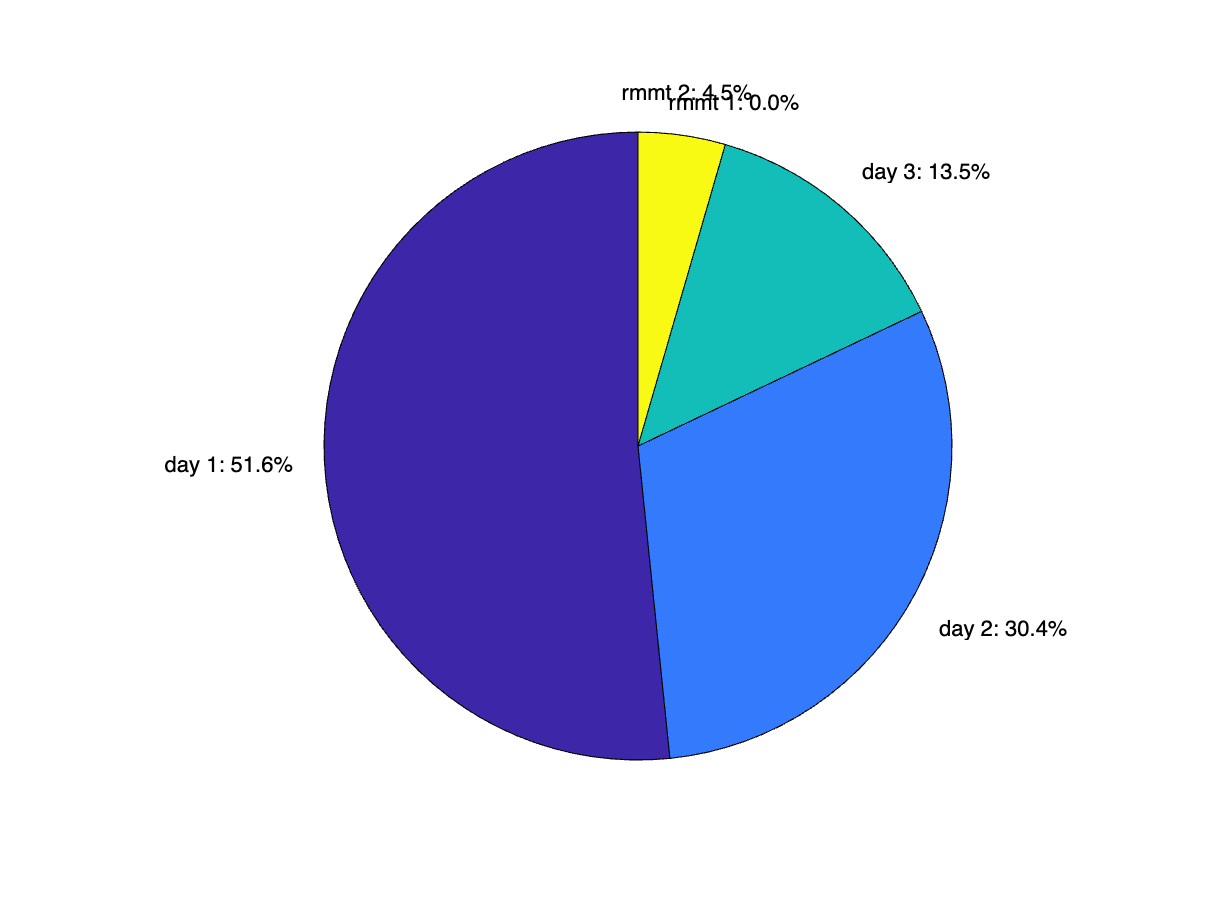

values = [us_r;roommate(1:2)];

labels = {'day 1','day 2','day 3','rmmt 1','rmmt 2'};

labels_with_pct = cell(1, numel(values));
for i = 1:numel(values)
    labels_with_pct{i} = sprintf('%s: %.1f%%', labels{i}, values(i)*100);
end
pie(values, labels_with_pct);

clear; clc; 
N =3;
reduction =20;
alpha = (100 - 20)/100;

%DISCRETIZATION
nb_poits = 1000;
xs = linspace(0,1,nb_poits);

p = 0.3; lambda = 0.25;

g_k =  @(u_k) -2*sqrt(u_k);
g_N = @(x_k) 0;

mu = NaN*zeros(nb_poits, N);
J = NaN*zeros(nb_poits, N+1);

for i = 1:nb_poits
    J(i,N+1) = g_N(xs(i));
end

for i = N:-1:1
    for ii = 1:nb_poits
        x_curret = xs(ii);
        us = xs(1:ii);
        nb_pos = length(us);
        J_temp = NaN*zeros(nb_pos,1);

        for iii=1:nb_pos
            x_next = xs(ii-iii+1);
            row = ii - iii +1 ;
            J_temp(iii) = g_k(us(iii)) + alpha*((1-p)*J(row,i+1))+ alpha*p*J(ceil(lambda*row),i+1);
        end

        [minval,minpos] = min(J_temp);
        J(ii,i) = minval; mu(ii,i) = us(minpos);

    end 
end 

%% simultion
n_scen = 10000;
val = zeros(n_scen,1);
for j=1:n_scen
    w = lambda*(rand(N,1)<p);
    us_r = zeros(N,1); vs_r = zeros(N+1,1); xs_r = zeros(N+1,1); xs_r(1) = 1;
    roommate = zeros(N,1);
    for i=1:N
        [~, idx] = min(abs(xs - xs_r(i))); %closest value to current x
        us_r(i) = mu(idx,i);
        xs_r(i+1) = (1-w(i))*(xs_r(i)-us_r(i));
        roommate(i) = xs_r(i)-us_r(i) - xs_r(i+1);
    end
    val(j,1) = sum(-2*sqrt(us_r).*(alpha.^[0:N-1])');
end

mean(val)

ans = -2.7731

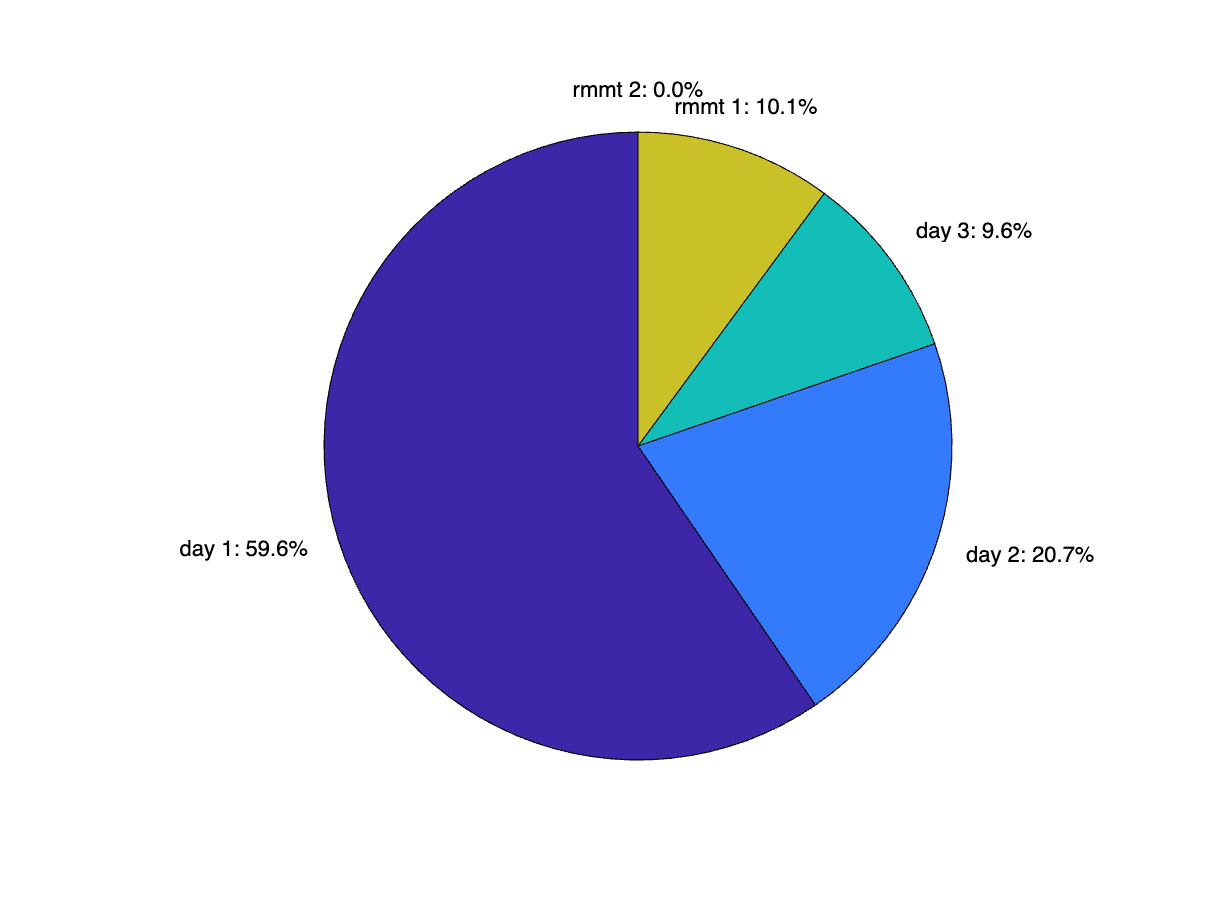

values = [us_r;roommate(1:2)];

labels = {'day 1','day 2','day 3','rmmt 1','rmmt 2'};

labels_with_pct = cell(1, numel(values));
for i = 1:numel(values)
    labels_with_pct{i} = sprintf('%s: %.1f%%', labels{i}, values(i)*100);
end
pie(values, labels_with_pct);